% Base paths and clearing
clear all
clc
addpath functions/SETUP/
addpath functions/SENSE/
addpath functions/ACT/

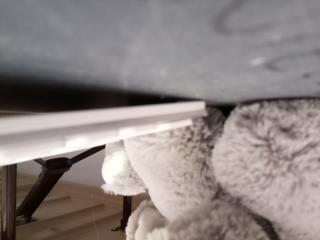

% Setup Pi
robotPi = raspi('192.168.16.68', 'pi', 'raspberry');
blinkLED = robotPi.AvailableLEDs{1};   
robotCam = cameraboard(robotPi,'Resolution','320x240');
SETUP_piCam(robotCam);  

img = snapshotCustom(robotCam);

piCamWindow = figure('name','Robot Pi Camera','NumberTitle','off','Visible','on');
figure(piCamWindow)
imshow(img,'Border','tight')


%     img = snapshotCustom(robotCam);
%     figure(piCamWindow)
%     imshow(img,'Border','tight')

I = imread("t3.jpg")

I = 480×640×3 uint8 array
I(:,:,1) =

   102   102   103   103   103   104   104   104   100   103   104   103    99    98    99   102   103   102   102   101   101   102   102   103   100   100   100   101   101   102   102   102   101   101   101   102   102   103   103   103   109   109   109   107   104   104   106   108   107   108   109   110   112   114   115   115   110   110   111   112   113   114   114   115   114   116   115   113   110   111   115   119   112   113   113   114   114   115   115   115   116   115   113   113   113   113   115   116   116   116   116   116   116   116   116   115   112   111   112   114   116   115   115   115   117   116   116   115   115   117   119   119   113   112   114   115   115   114   112   111   113   113   113   112   112   111   111   113   114   115   115   116   116   117   117   117   115   115   114   114   114   113   113   113   117   117   117   117   117   117   116   116   117   116   116   116   116   117   118   119  

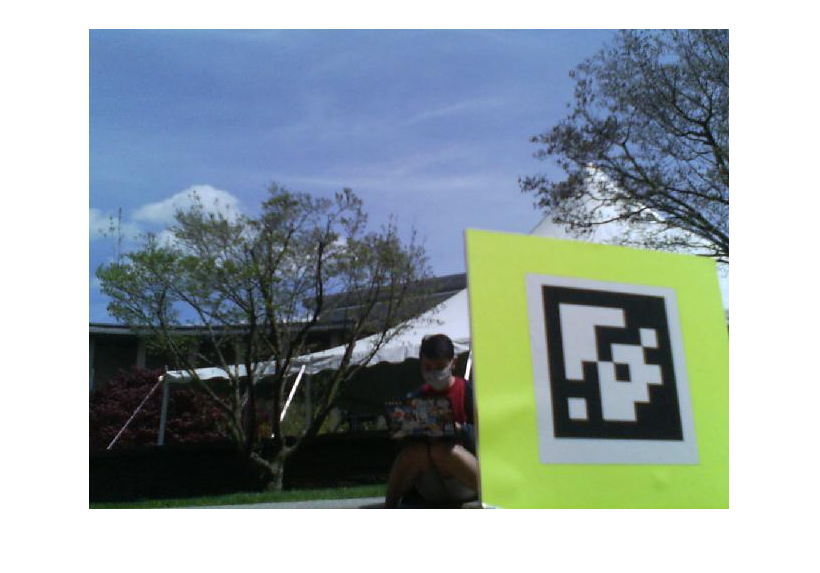

imshow(I)


focalLength    = [800, 800]; 
principalPoint = [320, 240];
imageSize      = [480, 640];

intrinsics = cameraIntrinsics(focalLength,principalPoint,imageSize)

intrinsics =   cameraIntrinsics with properties:

             FocalLength: [800 800]
          PrincipalPoint: [320 240]
               ImageSize: [480 640]
        RadialDistortion: [0 0]
    TangentialDistortion: [0 0]
                    Skew: 0
         IntrinsicMatrix: [3×3 double]



tagFamily = ["tag36h11"]

tagFamily = "tag36h11"


smallTagSize = 0.1135

smallTagSize = 0.1135


I = undistortImage(I,intrinsics,"OutputView","same");

[id,loc,pose] = readAprilTag(I,tagFamily,intrinsics,smallTagSize)

id = 5

loc =   466.7346  410.1234
  595.9047  412.8552
  576.2766  268.9715
  453.8461  256.7162


pose =   rigid3d with properties:

       Rotation: [3×3 double]
    Translation: [0.1538 0.0709 0.6029]


imagePoints =   524.0998  334.0677
  584.8150  337.8334
  532.6009  410.5266
  482.4964  348.1435


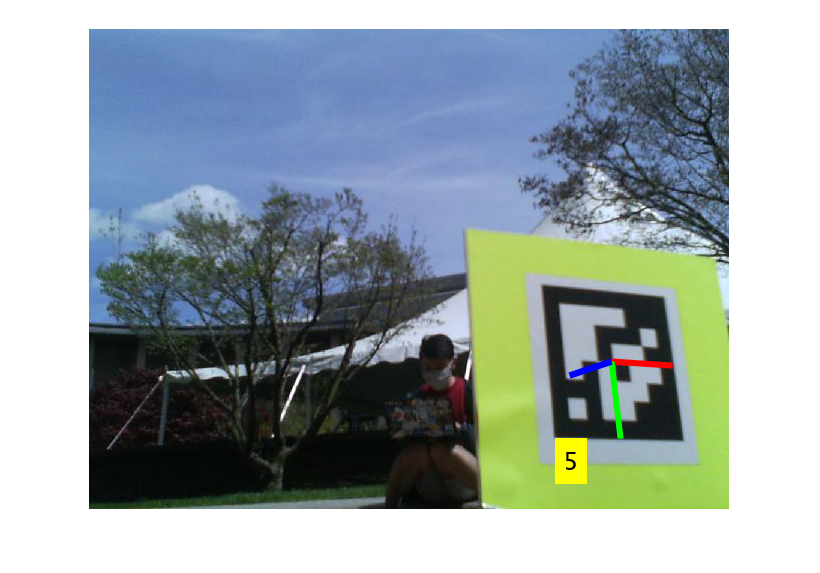


worldPoints = [0 0 0; smallTagSize/2 0 0; 0 smallTagSize/2 0; 0 0 smallTagSize/2];

for i = 1:length(pose)
    % Get image coordinates for axes.
    imagePoints = worldToImage(intrinsics,pose(i).Rotation, ...
                  pose(i).Translation,worldPoints)

    % Draw colored axes.
    I = insertShape(I,"Line",[imagePoints(1,:) imagePoints(2,:); ...
        imagePoints(1,:) imagePoints(3,:); imagePoints(1,:) imagePoints(4,:)], ...
        "Color",["red","green","blue"],"LineWidth",7);

    I = insertText(I,loc(1,:,i),id(i),"BoxOpacity",1,"FontSize",25);
    imshow(I)
end


%imshow(I)

%     disp("ID:")
%     disp(id)
%     disp("LOC:")
%     disp(loc)
%     
%     input("Next");
